S = ones(30, 1000);
S(10:11, 400:600) = 2;
S = S + randn(30,1000) * 0.23;
S(S < 0) = 0;
figure
waterfall(S')

view([45 45])

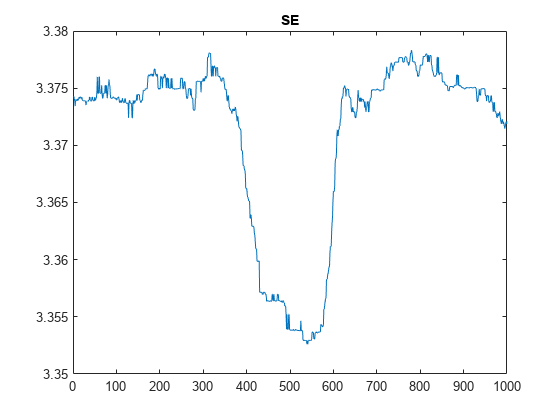


gmm = SEGMM(51);
gmm.detect(S)

figure
plot(gmm.H)
title("SE")

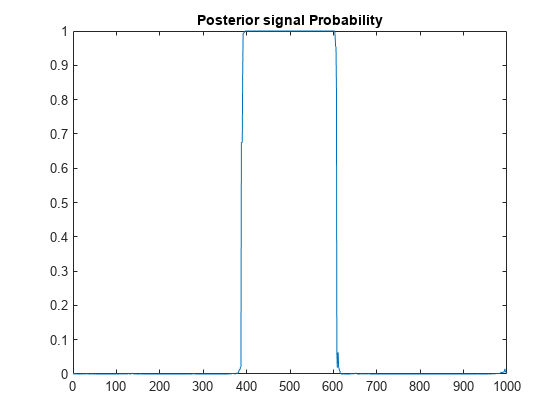


figure
plot(gmm.probs)
title("Posterior signal Probability")

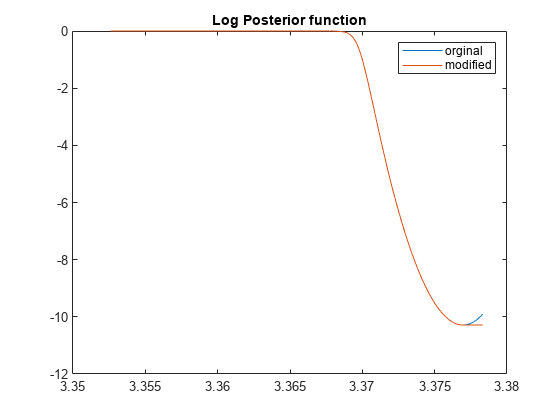


figure
plot(gmm.x, log(gmm.f))
title("Log Posterior function")
hold on
plot(gmm.x, log(gmm.fmod))
hold off
legend("orginal", "modified")

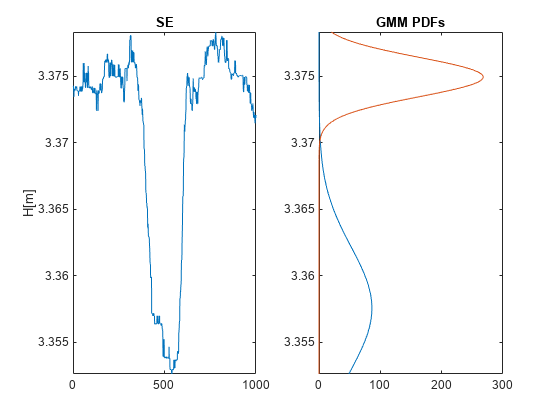



figure
subplot(121)
plot(gmm.H);
ylim([gmm.Hmin, gmm.Hmax])
title("SE")
ylabel("H[m]")
subplot(122)
plot(gmm.pdf, gmm.x)
ylim([gmm.Hmin, gmm.Hmax])
title("GMM PDFs")


gmm

gmm =   SEGMM with properties:

         MaxGMMIter: 200
    PosteriorThresh: 0.5000
                  M: 51
                  H: [3.3743 3.3743 3.3741 3.3739 3.3734 3.3739 3.3741 3.3739 3.3739 3.3739 3.3741 3.3739 3.3741 3.3742 3.3741 3.3742 3.3742 3.3742 3.3741 3.3742 3.3741 3.3739 3.3739 3.3739 3.3739 3.3739 3.3739 3.3739 3.3738 3.3735 3.3738 3.3738 … ]
              probs: [1.4439e-04 1.4646e-04 1.8057e-04 2.2577e-04 4.1475e-04 2.2577e-04 1.8512e-04 2.1587e-04 2.2075e-04 2.1587e-04 1.8123e-04 2.1587e-04 1.8123e-04 1.5347e-04 1.8123e-04 1.5347e-04 1.4991e-04 1.5347e-04 1.8123e-04 1.5347e-04 … ]
               mu_n: 3.3749
               mu_s: 3.3575
            sigma_n: 0.0015
            sigma_s: 0.0046
          converged: 1
             n_iter: 12
                 LL: 4.3223e+03
                mon: 0
               fmin: 3.4121e-05
               fmax: 1
                 Ht: 3.3698
             contam: 0.0011
        